%% You need to install "Signal Processing Toolbox" addon
close all;
clear;
clc;


## Setting

%% Signal Generation
sig_fs = 10000; % 샘플링 주파수
sig_freq_start = 1000; % 시작 주파수
sig_freq_stop = 1; % 끝 주파수
sig_perdec = 8; % decade당 포인트 수
sig_mode = 1; % 모드 선택 (interval: 1 또는 repetition: 2)
% Mode 1 only, 지속 시간 설정
sig_interval = 4;
% Mode 2 only, 반복 횟수 설정
sig_rep = 8;

%% DAC Settings % DAC_model: "Current steering DAC with Unary + Binary DAC Settings
DAC_bit = 9; % 양자화할 비트수
DAC_bitbinary = 2;                % Binary parts of DAC [bit]
DAC_bitunary = DAC_bit - DAC_bitbinary; % Unary parts of DAC [bit]
size_LSB = 0.08;           % LSB of DAC [A]
stdev = 0.0125;   % Standard deviation of MOSFET Vgs mismatch [A]
iteration = 5000;            % DAC specification checking iteration, ~1s/10^5cycles by prealloc algorithm [#] 


% PART I: Current mirror - Transistor Match Settings
Current_amplifier = "Current mirror"; % [1] Current mirror [2] Transimpedance amplifier
curr_amp = 1;              % Amplification level of current mirror [A/A]
curr_mismatch = 0.0001;    % Standard deviation of MOSFET Vgs mismatch [A]

## Gen

current_signal = [];
sig_phase = 0;
sig_frequencies = logspace(log10(sig_freq_start), log10(sig_freq_stop), (log10(sig_freq_start)-log10(sig_freq_stop))*sig_perdec+1); % 주파수 벡터

if sig_mode == 1
    sig_t = 0:1/sig_fs:sig_interval-1/sig_fs; % 시간 벡터
    % signal의 크기 미리 지정
    current_signal = zeros(1, length(sig_frequencies)*length(sig_t));
    
    for i=1:length(sig_frequencies)
        sig_f=sig_frequencies(i);
        sig_y=sin(2*pi*sig_f*sig_t+sig_phase);
        current_signal((i-1)*length(sig_t)+1:i*length(sig_t)) = sig_y;
        sig_phase=sig_phase+2*pi*sig_f*sig_interval;
    end

    time_arr = sig_interval*ones(1, length(sig_frequencies));
    time_vector=linspace(0,sig_interval*length(sig_frequencies),length(current_signal));

elseif sig_mode == 2    
    % signal과 time_arr의 크기 미리 지정
    signal_length = sum(floor(sig_rep./sig_frequencies)*sig_fs + 1);
    current_signal = zeros(1, signal_length);
    time_arr = zeros(1, length(sig_frequencies));
    
    idx_signal=1; % signal 배열 인덱스
    
    for i=1:length(sig_frequencies)
        f=sig_frequencies(i);
        interval=sig_rep/f;
        t=0:1/sig_fs:interval-1/sig_fs;
        y=sin(2*pi*f*t+sig_phase);
        
        idx_end_signal=idx_signal+length(y)-1; % 현재 반복에서 추가될 y의 마지막 인덱스
        current_signal(idx_signal:idx_end_signal)=y; % y 추가
        idx_signal=idx_end_signal+1; % 다음 반복을 위해 인덱스 업데이트
        time_arr(i)=interval; % interval 추가
        sig_phase=sig_phase+mod(2*pi*f*interval,2*pi); 
    end
    
    time_vector=linspace(0,sum(time_arr),length(current_signal));
end

time_vector = transpose(time_vector);
current_signal = transpose(current_signal);
time_arr = transpose(time_arr);

levels = 2^DAC_bit; % 양자화 레벨 수
range = max(current_signal) - min(current_signal); % 최대값과 최소값 차이
step = range / levels; % 양자화 간격

% 양자화된 전류 신호 계산 및 저장
quantized_signal = min(current_signal) + floor((current_signal - min(current_signal)) / step) * step;

% 양자화된 전류 신호의 이진 표현 계산 및 저장
binary_signal = dec2bin(round((quantized_signal - min(current_signal)) / step), DAC_bit);
integer_binary_signal = zeros(size(binary_signal)); % 이진 표현을 정수형 배열로 변환하여 저장할 배열 초기화
integer_binary_signal(:) = binary_signal(:) - '0'; % 각 문자열을 정수형 배열로 변환하여 저장 (벡터화)
integer_binary_signal(:,1) = [];

% fig1 = figure();
% subplot(2, 1, 1);
% scatter(time_vector, quantized_signal, "r");
% hold on;
% plot(time_vector, current_signal, "k");
% hold off;
% title('Perturbated Signal');
% xlabel('Time (sec)');
% ylabel('Magnitude (A)');
% 
% subplot(2, 1, 2);
% scatter(time_vector, quantized_signal, "r");
% hold on;
% plot(time_vector, current_signal, "k");
% hold off;
% axis([max(time_vector)*1/10000, max(time_vector)*2/10000, min(current_signal)-0.01, max(current_signal)+0.01]);
% title('Perturbated signal (Zoomed)');
% xlabel('Time (sec)');
% ylabel('Magnitude (A)');
% grid on;

## DAC

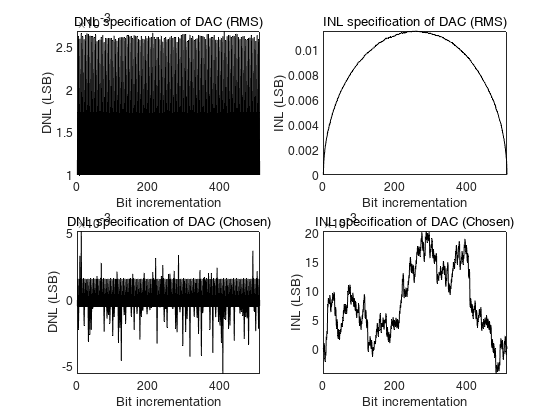

% Random transistor current variation generation
tr_sum = 2^DAC_bit - 1;
tr_matrix = normrnd(size_LSB, stdev*size_LSB, iteration, tr_sum);

% Transistor grouping for every iteration
var_matrix = zeros(iteration, 2^DAC_bitunary+DAC_bitbinary-1);
for loop_num = 1:iteration
    % Given transistor value per iteration
    tr_row = tr_matrix(loop_num,:);
    % unary tr groupings: 2^bit_bi ... 2^bit_bi (X (2^bit_un-1))
    for un_trgroup = 1:(2^DAC_bitunary-1)
        trgroup = tr_row(1, ((un_trgroup-1)*2^DAC_bitbinary+1):(un_trgroup*2^DAC_bitbinary));
        var_matrix(loop_num, un_trgroup)=sum(trgroup, 'all');
    end
    % binary tr groupings: 2^(bit_bi-1), 2^(bit_bi-2), ... , 1 (X bit_bi)
    frontval = (2^DAC_bitbinary)*(2^DAC_bitunary-1);
    loopval = 0;
    for bi_trgroup = 1:DAC_bitbinary
        a = (frontval+loopval+1);
        b = (frontval+loopval+2^(DAC_bitbinary-bi_trgroup));
        trgroup = tr_row(1, (frontval+loopval+1):(frontval+loopval+2^(DAC_bitbinary-bi_trgroup)));
        loopval = loopval + 2^(DAC_bitbinary-bi_trgroup);
        var_matrix(loop_num, (2^DAC_bitunary-1)+bi_trgroup)=sum(trgroup, 'all');
    end
end

% Decoder for switch operation
decode_matrix = zeros(2^DAC_bit, 2^DAC_bitunary-1+DAC_bitbinary);
for in = 1:2^DAC_bit
    % Separate unary / binary bit
    separation_un = fix((in-1)/(2^DAC_bitbinary));
    separation_bi = mod((in-1),2^DAC_bitbinary);
    % Decode: unary part
    for dec_one = 2^DAC_bitunary-separation_un:2^DAC_bitunary-1
        decode_matrix(in, dec_one) = 1;
    end
    % Decode: binary part
    decode_matrix(in, 2^DAC_bitunary:2^DAC_bitunary-1+DAC_bitbinary) = flip(de2bi(separation_bi,DAC_bitbinary),2);
end

% Multyply matrixes
calc_matrix = var_matrix * transpose(decode_matrix);

% Get error
ideal_range = 0:2^DAC_bit-1;
ideal_matrix = repmat(ideal_range, iteration, 1);
ideal_matrix = size_LSB * ideal_matrix;
error_matrix = calc_matrix - ideal_matrix;

% Calibration of INL values
cali_INL_matrix = error_matrix-(error_matrix(:,end)-error_matrix(:,1))/(2^DAC_bit)*(0:1:(2^DAC_bit-1));
cali_DNL_matrix = transpose(diff(transpose(cali_INL_matrix)));

% Apply RMS, get INL
rms_INL_matrix = zeros(1,2^DAC_bit);
chs_INL_matrix = zeros(1,2^DAC_bit);
for digital_num = 1:2^DAC_bit
    cali_column = cali_INL_matrix(:,digital_num);
    rms_INL_matrix(1,digital_num) = rms(cali_column);
    chs_INL_matrix(1,digital_num) = cali_column(1);
end

% Get DNL
rms_DNL_matrix = zeros(1,2^DAC_bit-1);
chs_DNL_matrix = zeros(1,2^DAC_bit-1);
for digital_num = 1:2^DAC_bit-1
    cali_column = cali_DNL_matrix(:,digital_num);
    rms_DNL_matrix(1,digital_num) = rms(cali_column);
    chs_DNL_matrix(1,digital_num) = cali_column(1);
end

% Implementation of current from generated signal using chosen DAC
chs_calc_matrix = calc_matrix(1,:);
chs_pert_signal = bit2int(transpose(integer_binary_signal), DAC_bit, true);
kkkk = transpose(chs_pert_signal);

% Chosen DAC for the test
DAC_output = zeros(1, length(chs_pert_signal));
for chs_index = 1:length(chs_pert_signal)
    chs_value = chs_calc_matrix(:, chs_pert_signal(:, chs_index)+1);
    DAC_output(chs_index) = chs_value;
end

% Plot DNL / INL
fig2 = figure();
subplot(2, 2, 1);
plot(rms_DNL_matrix, "k");
axis([0, 2^DAC_bit, -inf, inf]);
title('DNL specification of DAC (RMS)');
xlabel('Bit incrementation');
ylabel('DNL (LSB)');

subplot(2, 2, 2);
plot(rms_INL_matrix, "k");
axis([0, 2^DAC_bit, -inf, inf]);
title('INL specification of DAC (RMS)');
xlabel('Bit incrementation');
ylabel('INL (LSB)');

subplot(2, 2, 3);
plot(chs_DNL_matrix, "k");
axis([0, 2^DAC_bit, -inf, inf]);
title('DNL specification of DAC (Chosen)');
xlabel('Bit incrementation');
ylabel('DNL (LSB)');

subplot(2, 2, 4);
plot(chs_INL_matrix, "k");
axis([0, 2^DAC_bit, -inf, inf]);
title('INL specification of DAC (Chosen)');
xlabel('Bit incrementation');
ylabel('INL (LSB)');

## Current Amp

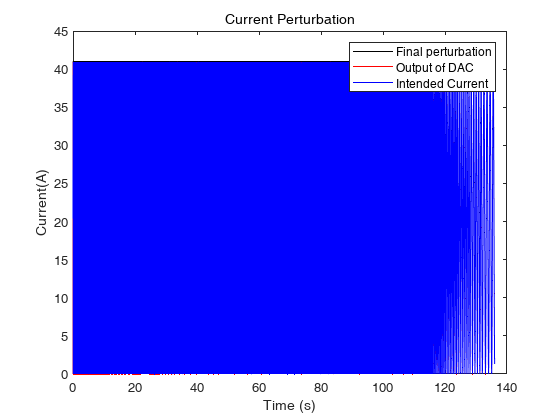

% Digital command comming through DAC + current mirror
% Output: Perterbated current flowing through the battery

pert_mean = mean(DAC_output, 'all');
pert_devmax = max(abs(DAC_output-pert_mean));
pert_mismatch = 1+(pert_devmax*curr_mismatch).*randn(1,1);
pert_outMirror = curr_amp*DAC_output*pert_mismatch;

pert_testsignal = pert_devmax*current_signal+pert_mean*ones(length(current_signal),1);

fig3 = figure();
pert_mir = plot(time_vector, pert_outMirror, "k");
hold on;
pert_dac = plot(time_vector, DAC_output, "r");
pert_tar = plot(time_vector, pert_testsignal, "b");
hold off;
title('Current Perturbation');
xlabel('Time (s)');
ylabel('Current(A)');
legend([pert_mir pert_dac pert_tar],{'Final perturbation', 'Output of DAC', 'Intended Current'});

## Battery

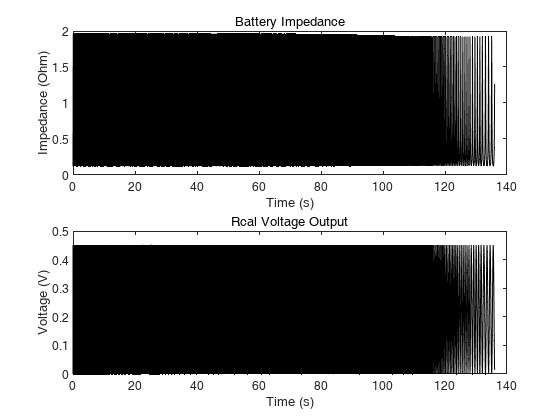

% PART I: Battery Settings
batt_dcCurrent = 2.5; %[A]
batt_dcVoltage = 4.8; %[V]

% PART I: Rcal Settings
Rcal = 5;                  % Value of calibration resistor [Ohm]

% PART I: Multi-Order Randle's Settings
rndl_order = 2;            % Order of the Randle's circuit [int # of range 0-2]
% PART I-1: 0th-order Randle's circuit options
rndl_Rs = 0.011;             % Internal electrolyte resistance of battery [Ohm]
% PART I-2: 1st-order Randle's circuit options
rndl_Rct = 0.005;           % Internal interface resistance of battery [Ohm]
rndl_Cdl = 3.184;       % Internal eletrode capacitance of battery [F]
% Part I-3: 2nd-order Randle's circuit options
rndl_Rsp = 0.001;          % Second pole resistance of AC perturbated battery [Ohm]
rndl_Csp = 10^(-15);       % Second pole capacitance of AC perturbated battery [F]

rndl_A = 1/rndl_Rct + rndl_Cdl*sig_fs;
rndl_B = - rndl_Cdl*sig_fs;
rndl_C = 1/rndl_Rsp + rndl_Csp*sig_fs;
rndl_D = - rndl_Csp*sig_fs;

rndl_temp1 = filter([1 0], [rndl_A rndl_B], pert_outMirror);
rndl_temp2 = filter([1 0], [rndl_C rndl_D], pert_outMirror);

if rndl_order == 0
    batt_voltageAC = pert_outMirror*rndl_Rs;
elseif rndl_order == 1
    batt_voltageAC = rndl_temp1 + pert_outMirror*rndl_Rs;
elseif rndl_order == 2
    batt_voltageAC = rndl_temp1 + rndl_temp2 + pert_outMirror*rndl_Rs;
end
batt_voltage = batt_voltageAC + batt_dcVoltage*ones(1,length(batt_voltageAC));
batt_current = pert_outMirror + batt_dcCurrent*ones(1,length(pert_outMirror));

% Voltage output from Rcal
rcal_voltage = rndl_Rs * pert_outMirror;

% Plotting battery impedance output in time domain
batt_impTime = zeros(1, length(batt_voltageAC));
for rndl_index = 1:length(batt_voltageAC)
    batt_impTime(rndl_index) = batt_voltage(rndl_index)/batt_current(rndl_index);
end

% Presetting for digital calculation
digital_freqrange = length(time_arr);
digital_list = zeros(1, digital_freqrange);
digital_duration = 0;
for digital_range = 0:1:digital_freqrange-1
    digital_list(digital_range+1) = 1/(sig_freq_stop*10^(digital_range/sig_perdec));
    digital_duration = digital_duration + digital_list(digital_range+1);
end % list of duration per frequency

% Ideal battery impedance calculation
batt_impIdeal = rndl_Rs + rndl_Rct./(1+1i*2*pi*sig_frequencies*rndl_Rct*rndl_Cdl) + rndl_Rsp./(1+1i*2*pi*sig_frequencies*rndl_Rsp*rndl_Csp);
batt_idealReal = real(batt_impIdeal);
batt_idealImag = imag(batt_impIdeal);
batt_idealMag = abs(batt_impIdeal);
batt_idealPhs = angle(batt_impIdeal);

digital_input = quantized_signal;
digital_voltage = batt_voltageAC;
digital_voltageRcal = rcal_voltage;

fig4 = figure();
subplot(2, 1, 1);
plot(time_vector, batt_impTime, 'k');
title('Battery Impedance');
xlabel('Time (s)');
ylabel('Impedance (Ohm)');

subplot(2, 1, 2);
plot(time_vector, rcal_voltage, 'k');
title('Rcal Voltage Output');
xlabel('Time (s)');
ylabel('Voltage (V)');

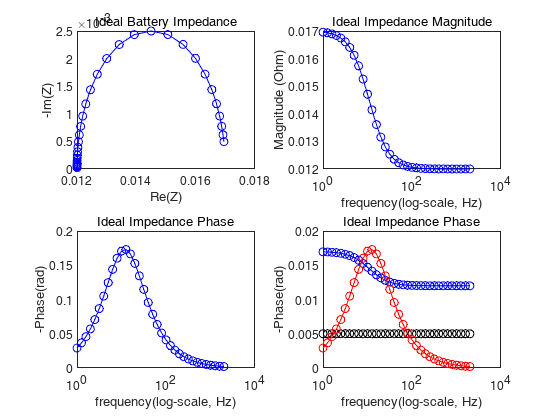


fig5 = figure();
subplot(2, 2, 1);
plot(batt_idealReal, -batt_idealImag, '-o', 'Color', 'blue');
title('Ideal Battery Impedance');
xlabel('Re(Z)');
ylabel('-Im(Z)');

subplot(2, 2, 2);
semilogx(sig_frequencies, batt_idealMag, '-o', 'Color', 'b');
title('Ideal Impedance Magnitude');
xlabel('frequency(log-scale, Hz)');
ylabel('Magnitude (Ohm)');

subplot(2, 2, 3);
semilogx(sig_frequencies, -batt_idealPhs, '-o', 'Color', 'b');
title('Ideal Impedance Phase');
xlabel('frequency(log-scale, Hz)');
ylabel('-Phase(rad)');

subplot(2, 2, 4);
semilogx(sig_frequencies, batt_idealMag, '-o', 'Color', 'b');
hold on;
semilogx(sig_frequencies, Rcal/1000, '-o', 'Color', 'k')
semilogx(sig_frequencies, -batt_idealPhs/10, '-o', 'Color', 'r');
hold off;
title('Ideal Impedance Phase');
xlabel('frequency(log-scale, Hz)');
ylabel('-Phase(rad)');

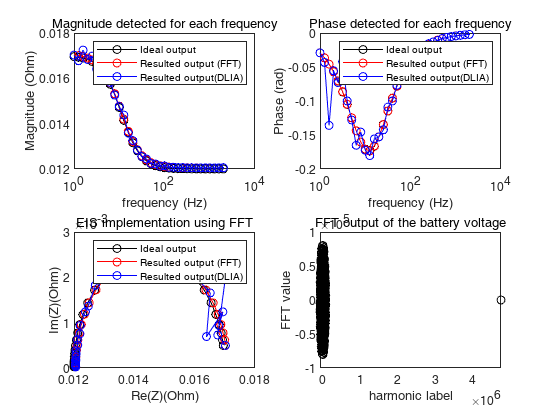

voltage_array = batt_voltageAC;
current_array = pert_devmax*current_signal;
% rcal_voltage
freq_array = sig_frequencies;
fs = sig_fs;

Digital_filter = "Fast fourier transform, Digital lock-in amplifier";

% Fast Fourier Transformation Methods
if contains(Digital_filter, "Fast fourier transform")
    % FFT calculation
    digital_fftInput = fft(current_array);
    digital_fftVoltage = fft(voltage_array);

    % Logarithmic approximation to implement harmonic
    digital_fftInputArr = zeros(1,length(time_arr));
    digital_fftVoltageArr = zeros(1,length(time_arr));
    for fft_index = 1:length(time_arr)
        f_fft = sig_fs*(0:(length(current_array)/2))/length(current_array);
        [~, digital_searchVal] = min(abs(f_fft-sig_frequencies(fft_index)));
        digital_fftInputArr(fft_index) = digital_fftInput(digital_searchVal);
        digital_fftVoltageArr(fft_index) = digital_fftVoltage(digital_searchVal);
    end
    digital_inputMag = abs(digital_fftInputArr);
    digital_inputPhs = angle(digital_fftInputArr);
    digital_voltageMag = abs(digital_fftVoltageArr);
    digital_voltagePhs = angle(digital_fftVoltageArr);

    % Magnitude ratio, phase difference calculation
    digital_magInfo = digital_voltageMag ./ digital_inputMag;
    digital_phsInfo = - digital_inputPhs + digital_voltagePhs;
    digital_phsInfo = mod(digital_phsInfo + pi, 2*pi) - pi;
    digital_realInfo = digital_magInfo .* cos(digital_phsInfo);
    digital_imagInfo = digital_magInfo .* sin(digital_phsInfo);
end

if contains(Digital_filter, "Digital lock-in amplifier")
    Z = zeros(size(sig_frequencies));
    start_idx = 1;
    for i = 1:length(time_arr)
        end_idx = start_idx + floor(time_arr(i)*sig_fs) - 1;
        cell_voltage = voltage_array(start_idx:end_idx);
        cell_current = current_array(start_idx:end_idx);
        cell_time = time_vector(start_idx:end_idx);
        front_real = sum(lowpass(real(transpose(cell_voltage) .* exp(-1i*2*pi*sig_frequencies(i)*cell_time)),0.1));
        front_imag = sum(lowpass(imag(transpose(cell_voltage) .* exp(-1i*2*pi*sig_frequencies(i)*cell_time)),0.1));
        back_real = sum(lowpass(real(cell_current .* exp(-1i*2*pi*sig_frequencies(i)*cell_time)),0.1));
        back_imag = sum(lowpass(imag(cell_current .* exp(-1i*2*pi*sig_frequencies(i)*cell_time)),0.1));
        Z(i) = (front_real+1i*front_imag) / (back_real+1i*back_imag);
        start_idx = end_idx + 1;
    end

    digital_dliaMag = abs(Z);
    digital_dliaPhs = angle(Z);
    digital_dliaReal = real(Z);
    digital_dliaImag = imag(Z);
end


fig7 = figure();
subplot(2, 2, 1);
digital_p1 = semilogx(sig_frequencies, batt_idealMag, '-o', 'Color', 'k');
title('Magnitude detected for each frequency');
xlabel('frequency (Hz)');
ylabel('Magnitude (Ohm)');
hold on;
digital_p2 = semilogx(sig_frequencies, digital_magInfo, '-o', 'Color', 'r');
digital_p3 = semilogx(sig_frequencies, digital_dliaMag, '-o', 'Color', 'b');
hold off;
legend([digital_p1 digital_p2 digital_p3], {'Ideal output', 'Resulted output (FFT)', 'Resulted output(DLIA)'});

subplot(2, 2, 2);
digital_p4 = semilogx(sig_frequencies, batt_idealPhs, '-o', 'Color', 'k');
title('Phase detected for each frequency');
xlabel('frequency (Hz)');
ylabel('Phase (rad)');
hold on;
digital_p5 = semilogx(sig_frequencies, digital_phsInfo, '-o', 'Color', 'r');
digital_p6 = semilogx(sig_frequencies, digital_dliaPhs, '-o', 'Color', 'b');
hold off;
legend([digital_p4 digital_p5 digital_p6], {'Ideal output', 'Resulted output (FFT)', 'Resulted output(DLIA)'});

subplot(2, 2, 3);
digital_p7 = plot(batt_idealReal, -batt_idealImag, '-o', 'Color', 'k');
title('EIS implementation using FFT');
xlabel('Re(Z)(Ohm)');
ylabel('Im(Z)(Ohm)');
hold on;
digital_p8 = plot(digital_realInfo, -digital_imagInfo, '-o', 'Color', 'r');
digital_p9 = plot(digital_dliaReal, -digital_dliaImag, '-o', 'Color', 'b');
hold off;
legend([digital_p7 digital_p8 digital_p9], {'Ideal output', 'Resulted output (FFT)', 'Resulted output(DLIA)'});

subplot(2, 2, 4);
digital_p10 = plot(digital_fftVoltage, 'o', 'Color', 'k');
title('FFT output of the battery voltage');
xlabel('harmonic label');
ylabel('FFT value');